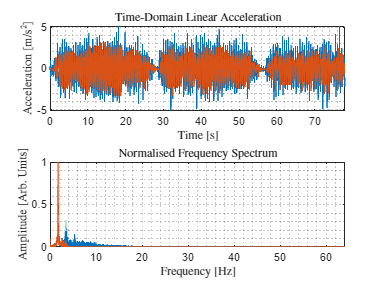

set(0,'defaulttextinterpreter','latex')
% Read walking linear acceleration data
y = dlmread('walkingdata_1.txt', '\t'); %#ok<DLMRD>
numSamples = length(y);
Ts = 0.0078;  % Sampling period
fs = 1/Ts; % Sampling frequency

% Time parameters
time_elapsed = Ts * numSamples;
t = (0:Ts:Ts * numSamples - Ts);
figure(1);

% Original Time-Domain Linear Acceleration
subplot(2, 1, 1);
plot(t, y, 'LineWidth', 0.5);
hold on;

% Design a low-pass filter
fc = 3; % [Hz]
fn =  2 * fc / fs; % Normalised cuttoff frequency
filter_order = 10;
[b, a] = butter(filter_order, fn, 'low');

% Apply the filter to the data
filtered_y_iir = filter(b, a, y);


% Filtered Time-Domain Linear Acceleration
plot(t, filtered_y_iir, 'LineWidth', 1);
title('Time-Domain Linear Acceleration');
xlabel('Time [s]');
ylabel('Acceleration  [$\mathrm{m/s^2}$]');
grid minor;
xlim([0 time_elapsed]);

% Compute and plot the Fourier Transform
frequencies = (fs/numSamples*(1:numSamples / 2));
ft_walk = fft(y);
max_amplitude_walk = max(abs(ft_walk));
norm_amplitude = abs(ft_walk(1:numSamples / 2)) / max_amplitude_walk;

% Original Normalised Frequency Spectrum
subplot(2, 1, 2);
plot(frequencies, norm_amplitude, 'LineWidth', 1);
hold on;

% Compute and plot the Fourier Transform of the filtered signal
ft_filtered = fft(filtered_y_iir);
max_amplitude_filtered = max(abs(ft_filtered));
norm_amplitude_filtered = abs(ft_filtered(1:numSamples / 2)) / max_amplitude_filtered;

% Filtered Normalised Frequency Spectrum
plot(frequencies, norm_amplitude_filtered, 'LineWidth', 1);
title('Normalised Frequency Spectrum');
xlabel('Frequency [Hz]');
ylabel('Amplitude [Arb. Units]');
grid minor;
xlim([0 max(frequencies)]);

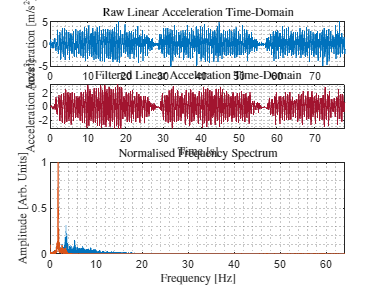

% Plot colours
Gray = [.5 .5 .5];
RGB_Violet = [0.4940 0.1840 0.5560];
RGB_Maroon = [0.6350 0.0780 0.1840];
RGB_Yellow = [0.9290 0.6940 0.1250];
RGB_Orange = [0.8500 0.3250 0.0980];
RGB_Forest = [0.4660 0.6740 0.1880];
RGB_Blue = [0 0.4470 0.7410];

figure(2);

% Adjust the position of each subplot
subplot(4, 1, 1);
plot(t, y, 'LineWidth', 0.5, 'Color', RGB_Blue);
title('Raw Linear Acceleration Time-Domain');
xlabel('Time [s]');
ylabel('Acceleration  [$\mathrm{m/s^2}$]');
grid minor;
xlim([0 time_elapsed]);

subplot(4, 1, 2);
plot(t, filtered_y_iir, 'LineWidth', 0.5, 'Color', RGB_Maroon);
title('Filtered Linear Acceleration Time-Domain');
xlabel('Time [s]');
ylabel('Acceleration  [$\mathrm{m/s^2}$]');
grid minor;
xlim([0 time_elapsed]);

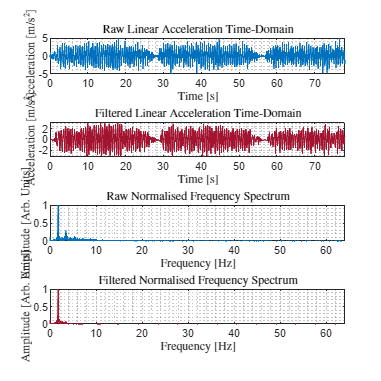


subplot(4, 1, 3);
plot(frequencies, norm_amplitude, 'LineWidth', 0.5, 'Color', RGB_Blue);
title('Raw Normalised Frequency Spectrum');
xlabel('Frequency [Hz]');
ylabel('Amplitude [Arb. Units]');
grid minor;
xlim([0 max(frequencies)]);


subplot(4, 1, 4);
plot(frequencies, norm_amplitude_filtered, 'LineWidth', 0.5, 'Color', RGB_Maroon);
title('Filtered Normalised Frequency Spectrum');
xlabel('Frequency [Hz]');
ylabel('Amplitude [Arb. Units]');
grid minor;
xlim([0 max(frequencies)]);

% Adjust the size of the entire figure
set(gcf, 'Position', [100, 100, 800, 800]);


% print -depsc BNO085_Walking_FFT_Plot